## Instructions

- Run each cell in order.

- Modify the lines that have green comments.

- This notebook, by default, assumes that time/samples are rows and channels are columns.

- Feel free to try more involved preprocessing steps, but assign your results back to the appropriate variables.

## Preprocessing

### Step 1: Load the dataset

clearvars
load("datasets\training_dataset.mat")

### Step 2: Visualize the raw data

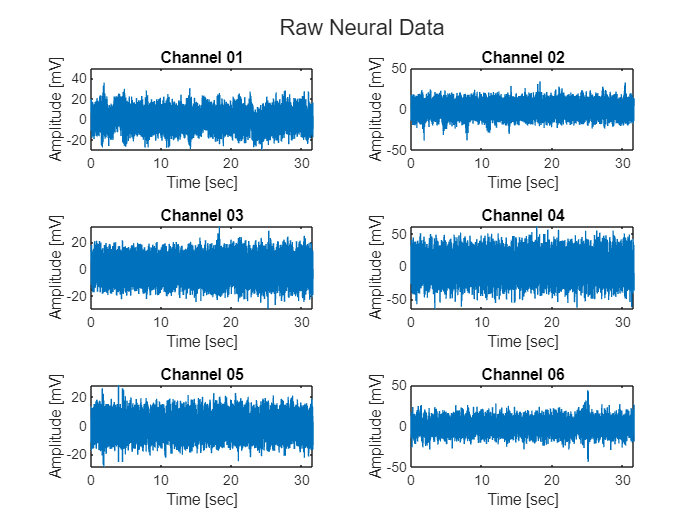

fig_1 = plot_raw_data(experiment_data);

### Step 3: Filter the data

#### A. Provide information for designing the fiter

Assuming you want to use a high-pass filter to denoise the neural signals, answer the following questions:

%%%%%%%%%%%%%%%%%%%%%%%%%%%%% CHANGE THIS CODE %%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% What is the sampling frequency of your signals in units of Hz?
sample_rate = 7; % Change this random value to the actual value of the sample rate
% What cutoff frequency (in Hz) would you use for a highpass filter?
cut_off_freq = 1; % Change this random value
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

#### B. Design the filter and apply it to the signal

The function `butter` designs a filter using three arguments: filter order, normalized cut off frequency, and filter type.

It returns the transfer function coefficients that match the provided specifications:


$$H(z) = \frac{B(z)}{A(z)} = \frac{b(1) + b(2)\,z^{-1} + b(n+1)\,z^{-n}}{a(1) + a(2)\,z^{-1} + a(n+1)\,z^{-n}}$$


filt_order = 4;
norm_cut_off = cut_off_freq / (sample_rate/2);
[b, a] = butter(filt_order, norm_cut_off, 'high'); % 4th order highpass filter

To apply the filter, we pass the transfer function to a precompiled method (`FilterX`) that has been optimized for speed

ch_init_conds = zeros(filt_order, 6); %initial conditions for filter for all channels
[filt_neural_data, ~] = FilterX(b, a, experiment_data.raw_neural_data, ch_init_conds);

#### Step 4: Visualize the Filtered Data

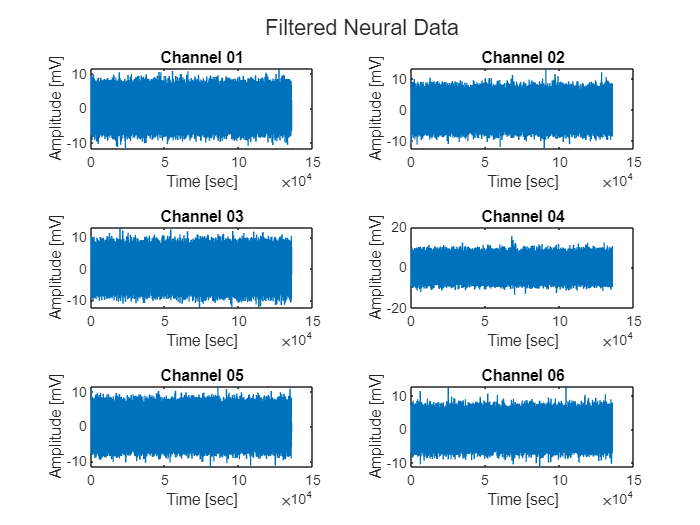

fig_2 = plot_filt_data(filt_neural_data, sample_rate);

## Spike Detection

If your signal processing steps worked well, you should be able to detect some action action potentials.

### Step 1: Find the locations of the spikes (action potentials) in all channels

Your goal for this step is to identify the locations in the `filt_neural_data` matrix, where spikes have ocurred.

You will start with an array that has the same shape as `filt_neural_data`, and whose entries have been initialized to zero.

spike_locations = zeros(size(filt_neural_data))

spike_locations =      0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0


Then, modify the code below so that it replaces `0`s with `1`s whenever you find a spike.

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% CHANGE THIS CODE %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
spike_locations = (randi(7000, size(spike_locations)) == 1); % This code generates random spike locations. Replace with a spike detection algorithm
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
spike_locations

spike_locations = 948199×6 logical array
   0   0   0   0   0   0
   0   0   0   0   0   0
   0   0   0   0   0   0
   0   0   0   0   0   0
   0   0   0   0   0   0
   0   0   0   0   0   0
   0   0   0   0   0   0
   0   0   0   0   0   0
   0   0   0   0   0   0
   0   0   0   0   0   0


### Step 2: Visualize the spike locations as spike trains in a raster plot

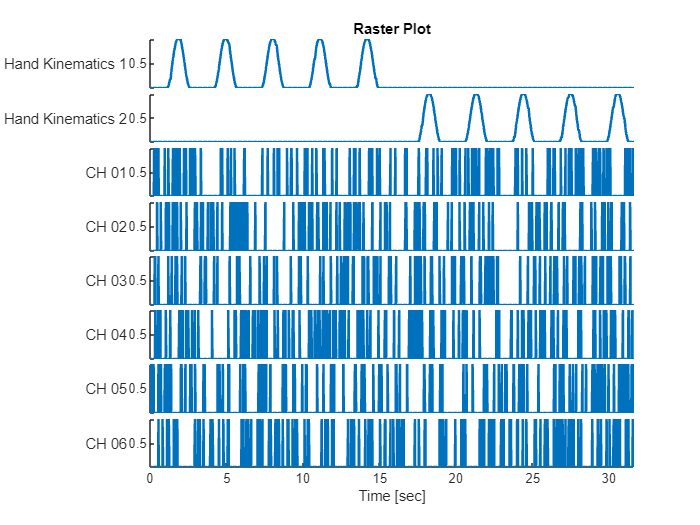

fig_3 = plot_spike_trains(spike_locations, experiment_data);

### Step 3: Plot the action potential waveforms using the spike locations

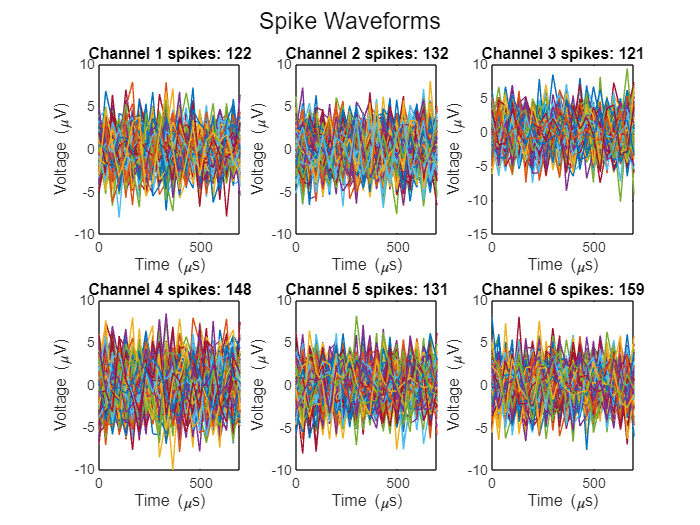

spike_waveforms = plot_action_potentials(filt_neural_data, 'Spike Waveforms', spike_locations);

### Step 4: Calculate the SNR of each detected spike

First, let's explore how we have stored the waveforms. 

`spike_waveforms` is a cell array that has one row per channel.

spike_waveforms

spike_waveforms = 6×1 cell array
    {1×122 cell}
    {1×132 cell}
    {1×121 cell}
    {1×148 cell}
    {1×131 cell}
    {1×159 cell}


Each one of those rows contains is also a cell array containing a variable number of waveforms. In order to access the waveforms, you need to specify the channel you want, and then the waveform you are interested in.

chan_idx = 1;
spike_waveforms{chan_idx}

ans = 1×122 cell array
    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×

waveform_idx = 7;
waveform_data = spike_waveforms{chan_idx}{waveform_idx}

waveform_data = 22×1 single column vector
    0.8928
   -4.8866
    2.4408
   -0.8418
    1.6356
   -0.2042
    1.7079
   -4.4868
    1.6596
    4.1897


The waveform itself is a vector containing 22 samples of neural data.

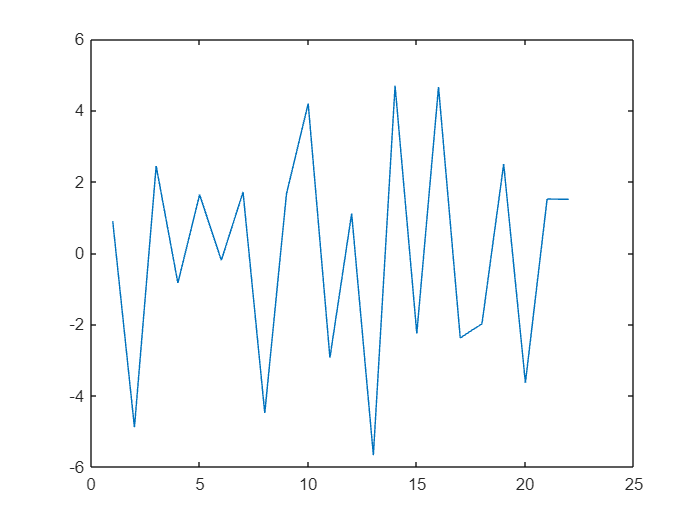

figure
plot(waveform_data)

Now, consider this image which shows action potentials for a range of SNRs. Based on SNR, how would you determine which is the best action potential?

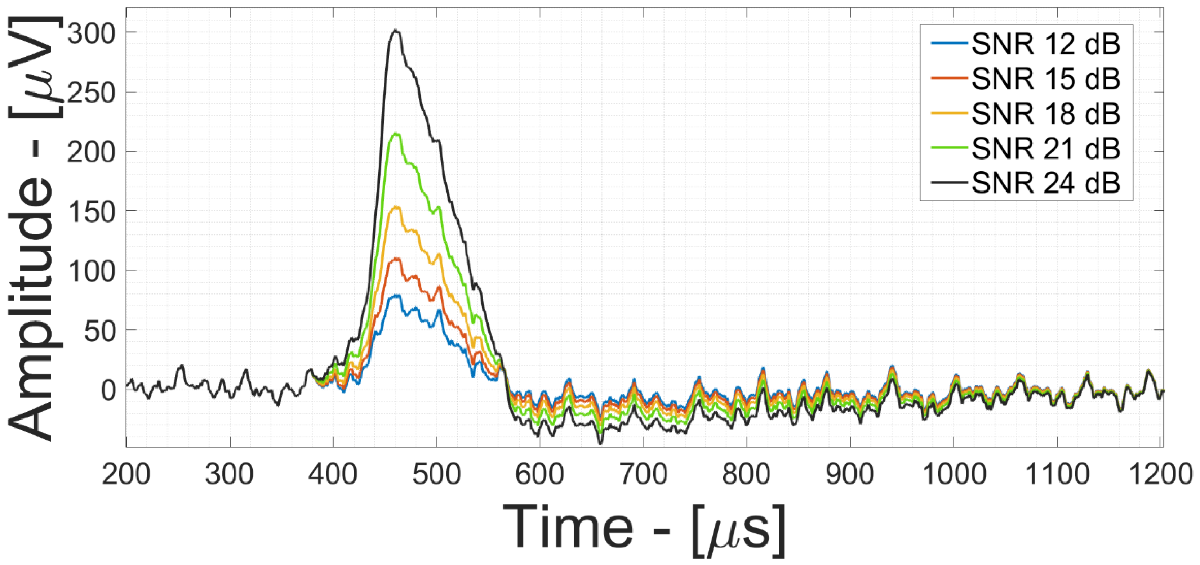

Calculate the SNR of each waveform in spike waveforms. Use the following code to access each waveform:

for chan_idx = 1:6 % for each channel
    chan_waveforms = spike_waveforms{chan_idx};
    for waveform_idx = 1:length(chan_waveforms) % for each waveform in the channel
        waveform_data = chan_waveforms{waveform_idx};
        %%%%%%%%%%%%%%%%%%%%%%%% YOUR SNR CODE GOES HERE %%%%%%%%%%%%%%%%%%%

        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    end
end

After you've calculated SNRs, make sure to **plot the SNR values** and **run stats**!

## Feature Extraction

The only requirement for this section is that the size of your features must match the size of the kinematics. The reason for this is that the kinematics are acting as labels for your features. For more information, check notebook 03 on training the neural network.

%%%%%%%%%%%%%%%%%%%%%%%%% CHANGE THIS CODE %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
neural_features = filt_neural_data; % nonsensical code
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
assert(length(neural_features) == length(experiment_data.hand_kinematics))

## Helper Functions

function fig_handle = plot_raw_data(experiment_data)
[num_samples, num_chans] = size(experiment_data.raw_neural_data);
timestamps = (1:num_samples)/experiment_data.sample_rate;

fig_handle = figure;
fig_raw = tiledlayout("flow");
for i = 1:num_chans
    nexttile
    plot(timestamps, experiment_data.raw_neural_data(:,i))
    title(sprintf('Channel %02d', i))
    xlabel('Time [sec]')
    ylabel('Amplitude [mV]')
end
title(fig_raw, 'Raw Neural Data')
end


function fig_handle = plot_filt_data(neural_data, sample_rate)
[num_samples, num_chans] = size(neural_data);
timestamps = (1:num_samples)/sample_rate;

fig_handle = figure;
fig_raw = tiledlayout("flow");
for i = 1:num_chans
    nexttile
    plot(timestamps, neural_data(:,i))
    title(sprintf('Channel %02d', i))
    xlabel('Time [sec]')
    ylabel('Amplitude [mV]')
end
title(fig_raw, 'Filtered Neural Data')
end


function fig_handle = plot_spike_trains(spike_locations, experiment_data)
fig_handle = figure;
t = (0:1:length(spike_locations)-1)'/experiment_data.sample_rate;
raster_handle = stackedplot(t, [experiment_data.hand_kinematics, spike_locations], LineWidth=1.5);
raster_handle.DisplayLabels = ["Hand Kinematics 1", "Hand Kinematics 2", "CH 01", "CH 02", "CH 03", "CH 04", "CH 05", "CH 06"];
raster_handle.XLabel = "Time [sec]";
raster_handle.Title = "Raster Plot";
end


function spike_waveform_container = plot_action_potentials(data, plot_title, spike_trains)
[~, n_chans] = size(data);
figure()
sgtitle(plot_title)
spike_waveform_container = cell(n_chans,1);
for chan=1:n_chans
    neg_offset = -3;
    pos_offset = 18;
    spike_locations = spike_trains(:,chan);
    spike_locations = find(spike_locations == 1);
    spike_count = sum(spike_trains);
    spikes = cell(1, spike_count(chan));

    subplot(2, 3, chan)
    for spike_idx = 1:length(spikes)
        idx_start = spike_locations(spike_idx) + neg_offset;
        idx_end = spike_locations(spike_idx) + pos_offset;
        try
            spikes{spike_idx} = data(idx_start:idx_end, chan);
            plot(0:33:700, spikes{spike_idx});
        catch
        end
        hold on;
        spike_waveform_container{chan} = spikes;
    end
    xlabel('Time (\mus)')
    ylabel('Voltage (\muV)')
    hold off
    title(['Channel ' num2str(chan) ' spikes: ' num2str(length(spikes))])
end
end